*Copyright 2025 The MathWorks, Inc.*

# **EXERCISE 2 : Plug a custom downlink channel into the simulated 5G network   **

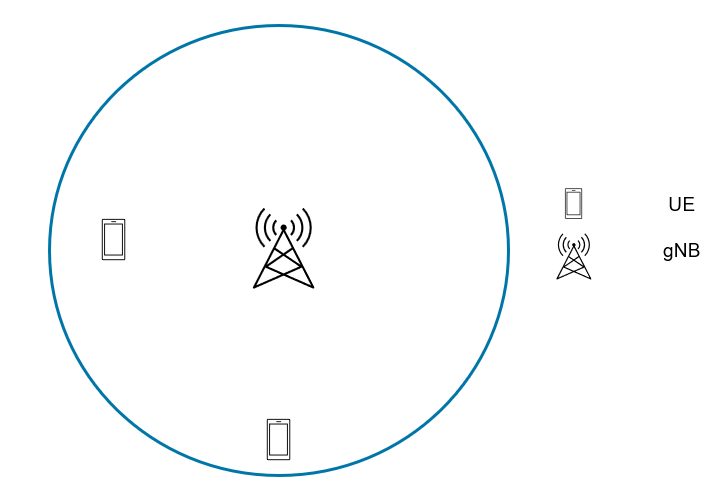

This excercise demonstrates the workflow to plug a custom channel into simulated 5G network. The goals are:

- Create a custom channel 

- Plug custom channel into the simulated network   

- Impair signal using the custom channel  

#### Initialize Variables and Wireless Network Simulator

all_figs = findall(0, 'type', 'figure');close(all_figs); % close all previous windows 
rng("default") % Reset the random number generator for reproducibility 
wirelessnetworkSupportPackageCheck; % Wireless Network Simulation package is installed
networkSimulator = wirelessNetworkSimulator.init;% Initialize the Wireless Network Simulator
cellRadius = 5000 ; % Radius of each cell (in meters)
numFrameSimulation = 25; % Number of frames to simulate

#### Create a 5G NR base station and configure its MAC scheduler

gNBPosition = [0 0 10];
gnb = nrGNB(Position=gNBPosition, ...
    ChannelBandwidth=20e6, ...
    DuplexMode="FDD", ...
    SubcarrierSpacing=30e3, ...
    PHYAbstractionMethod="none", ...
    NumTransmitAntennas=1, ...
    NumReceiveAntennas=1);
configureScheduler(gnb,CSIMeasurementSignalDL="CSI-RS",Scheduler="RoundRobin");

#### Create two UE nodes, specifying their positions in Cartesian coordinates

% Create a UE (User Equipment) node
numUEs = 2;
ueNames =["UE-1";"UE-2"];       % UE Name 
uePositions = [500 500 0; 4500 100 0]; % UE position
ue = nrUE(Position=uePositions, ...
    PHYAbstractionMethod="none", ...
    Name=ueNames,NumReceiveAntennas=1, ...
    NumTransmitAntennas=1);

#### Connect the UE nodes to the gNB node and enable full-buffer traffic in the downlink direction

connectUE(gnb,ue,FullBufferTraffic="DL")

#### Add the nodes to the network simulator.

addNodes(networkSimulator,gnb);
addNodes(networkSimulator,ue);

#### **Visualize the network that you have created **

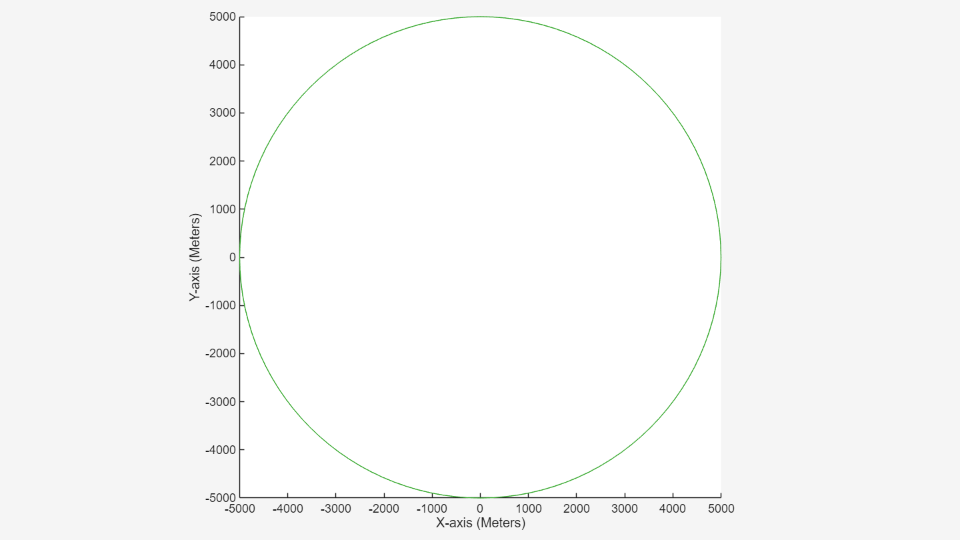

networkVisualizer = helperNetworkVisualizer(SampleRate=100); % Sample rate indicates the visualization refresh rate in Hertz
showBoundaries(networkVisualizer,gNBPosition,cellRadius,gnb.ID);% Show the cell boundary of each gNB

#### Retrieve OFDM information

% Retrieve OFDM information based on the number of resource blocks and subcarrier spacing
waveformInfo = nrOFDMInfo(gnb.NumResourceBlocks,gnb.SubcarrierSpacing/1e3);
sr = waveformInfo.SampleRate;

channelFilteringFlag = strcmp(gnb.PHYAbstractionMethod,"none");

# Task #1/3 Create a downlink CDL channel form gNB to UE-1

% Use nrCDLChannel() function to create a NR CDL channel  
% Store the channel in a variable named "CDLChannelgNBtoUE1"
% Hint:Type doc nrCDLChannel in the command window, and see the "Syntax" section.
% Note : use the following values to start with
% SampleRate=sr
% ChannelFiltering=channelFilteringFlag
% DelayProfile="CDL-D"
% MaximumDopplerShift=200
% DelaySpread=30e-9

% Write your code here 
CDLChannelgNBtoUE1 = nrCDLChannel(SampleRate=sr, ...
    ChannelFiltering=channelFilteringFlag, ...
    DelayProfile="CDL-D", ...
    MaximumDopplerShift=1600, ...
    DelaySpread=30e-9);

#### Set antenna array size 

% Size of antenna array, specified as [M N P Mg Ng], where:
% M and N are the number of rows and columns in the antenna array, respectively.
% P is the number of polarizations (1 or 2).
% Mg and Ng are the number of row and column array panels, respectively.
antennaSize = [1 1 1 1 1];

#### **Set antenna array for downlink CDL channel form gNB to UE-1**

CDLChannelgNBtoUE1.TransmitAntennaArray.Size = antennaSize;
CDLChannelgNBtoUE1.ReceiveAntennaArray.Size = antennaSize;

#### Create a downlink CDL channel form gNB to UE-2

CDLChannelgNBtoUE2 = nrCDLChannel(SampleRate=sr, ...
    ChannelFiltering=channelFilteringFlag);
CDLChannelgNBtoUE2.TransmitAntennaArray.Size = antennaSize;
CDLChannelgNBtoUE2.ReceiveAntennaArray.Size = antennaSize;

#### Save channel information for use during the simulation 

dlChannel = {CDLChannelgNBtoUE1,CDLChannelgNBtoUE2};
storeChannelInfo(dlChannel,gnb,ue,sr);

# Task #2/3 Add the custom channel to the wireless network simulator

% Use addChannelModel() function to define a function implementing a propagation channel model
% Hint: Click the link below and see the "Syntax" section.

### [Help on adding custom channel ](https://www.mathworks.com/help/releases/R2024b/comm/ref/wirelessnetworksimulator.addchannelmodel.html)

% Note : name the function implement the channel "addImpairment". To
% pass the function as an argument use @addImpairment

addChannelModel(networkSimulator,@addImpairment);

#### Enable Visualization

metricsVisualizer = helperNRMetricsVisualizer(gnb,ue,RefreshRate=100,PlotSchedulerMetrics=true,PlotPhyMetrics=false,LinkDirection=0);

#### Specify the simulation time in seconds. Run the simulation for the specified simulation time.

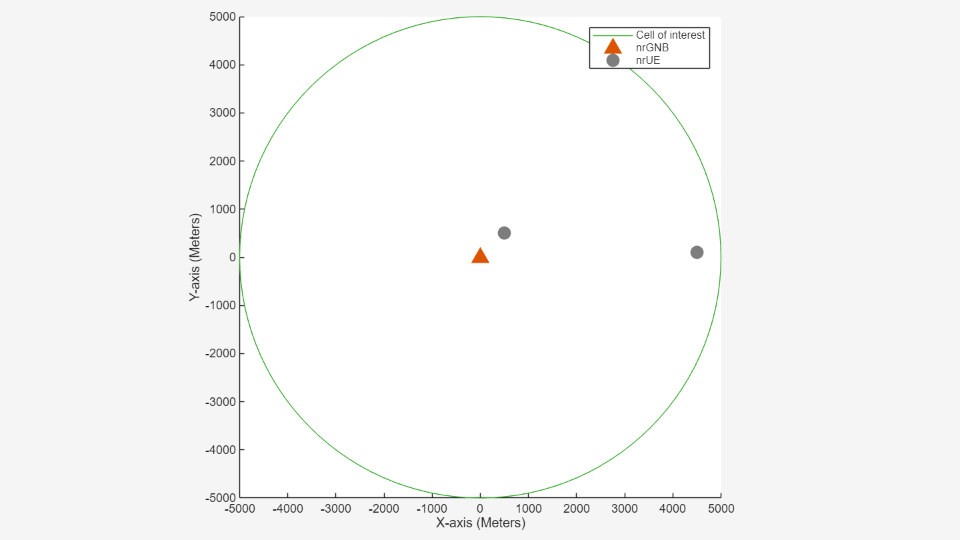

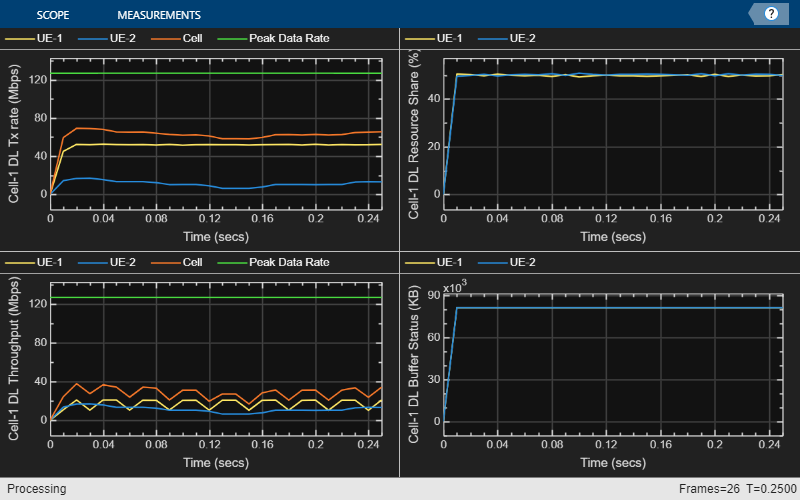

run(networkSimulator,numFrameSimulation*0.01)

#### Display Performance Indicators

displayPerformanceIndicators(metricsVisualizer)

Peak DL throughput: 126.91 Mbps. Achieved cell DL throughput: 28.47 Mbps
Achieved DL throughput for each UE: [17.09        11.39]
Peak DL spectral efficiency: 6.35 bits/s/Hz. Achieved DL spectral efficiency for cell: 1.42 bits/s/Hz
Block error rate for each UE in the DL direction: [0.665           0]



Clear persistent channel context

clear getSetChannelModel;

#### Getter and Setter for channel models 

function channelModelInfo = getSetChannelModel(varargin)
persistent channelModels;
if nargin == 1 % Set
    channelModels = varargin{1};
end
channelModelInfo = channelModels;
end

Follow these steps to create a custom channel model

- The simulator passes information about the receiver node and transmitter node as inputs to the custom function.

- Apply free space path loss between the base station and UE nodes. 

- Apply custom channel to the transmitted packets.

% addImpairment is a user-defined callback function invoked by the simulation engine
% whenever a packet is exchanged between any two nodes in the simulated network.

% rxInfo that passed to this function constains the following information
    % ID
    % Position
    % Velocity and more .. 
% txData that is passed function constains the following information
    % TransmitterID
    % TransmitterPosition
    % TransmitterVelocity
    % Power
    % CenterFrequency
    % Bandwidth
    % Sample rate
    % Antenna Configuration 
    % Tx Data and more ..
function outputData = addImpairment(rxInfo,txData)

outputData = txData;

% Calculate path loss based 

# Task #3/3 Calculate the distance between transmitter and receiver in meters

% Use norm() function to compute distance between AP and STA
% a = [0 3 1];
% b = [-2 1 5];
% d = norm(b-a)
% Hint: see the contents of outputData.TransmitterPosition, rxInfo.Position
% name the variable "distance"
% Calulate the distance between the transmitter and the receiver

distance = norm(txData.TransmitterPosition - rxInfo.Position);

% Wavelength calculation using the speed of light and center frequency.
lambda = physconst('LightSpeed')/txData.CenterFrequency;
% Free space path loss
pathLoss = fspl(distance, lambda);
% Adjust the power of the output data based on the path loss
outputData.Power = outputData.Power - pathLoss;
% Retrieve the channel model information that we created
channelModelInfo = getSetChannelModel();
% Obtain the maximum channel delay matrix from the channel model information
maxChannelDelayMatrix = channelModelInfo.MaxChannelDelayMatrix;
% Obtain the path filter from the channel model information
pathFilter = channelModelInfo.PathFilter;
% Get transmitter Id
txId = txData.TransmitterID;
% Get Receiver Id
rxId = rxInfo.ID;
% Get channel between Tx and Rx pair
channel = channelModelInfo.CDLChannels{txId,rxId};
% Get max delay between Tx and Rx pair which is sum of path delay and filter delay
maxDelay = maxChannelDelayMatrix(txId,rxId);
% Get path filter between Tx and Rx pair
filter = pathFilter{txId,rxId};
% Check if this is a downlink channel
downlinkChannel = ~isempty(channel);

if downlinkChannel
    % Start time of the current data/packet
    channel.InitialTime = outputData.StartTime;
    % Rx waveform is set to txData appended with path delay and filter delay in samples
    rxWaveform = [txData.Data; zeros(maxDelay,size(txData.Data,2))];
    % Pass the signal through channel
    % "outputData.Data" is the output signal
    % "outputData.Metadata.Channel.PathGains" is path gains captured at
    % every channel snapshot per Tx and Rx antenna pair
    % "outputData.Metadata.Channel.SampleTimes" Times when channel snapshot is taken
    [outputData.Data,outputData.Metadata.Channel.PathGains, outputData.Metadata.Channel.SampleTimes] = channel(rxWaveform);
    % Scale the power of the output data based on the path loss
    outputData.Data = outputData.Data.*db2mag(-pathLoss);
    % Duration of the signal
    outputData.Duration = outputData.Duration + (1/outputData.SampleRate)*maxDelay;
    % Path filters to model fractional delays

    outputData.Metadata.Channel.PathFilters = filter;
else
    % Set default values for channel parameters
    outputData.Metadata.Channel.PathGains = permute(ones(outputData.NumTransmitAntennas,rxInfo.NumReceiveAntennas),[3 4 1 2]) / sqrt(rxInfo.NumReceiveAntennas);
    outputData.Metadata.Channel.PathFilters = 1;
    outputData.Metadata.Channel.SampleTimes = 0;


    outputData.Data = outputData.Data.*db2mag(-pathLoss);
    numTxAnts = outputData.NumTransmitAntennas;
    numRxAnts = rxInfo.NumReceiveAntennas;
    H = fft(eye(max([numTxAnts numRxAnts])));
    H = H(1:numTxAnts,1:numRxAnts);
    H = H/norm(H);
    outputData.Data = txData.Data*H; % Apply channel to the waveform

end

end

#### Suggested Experiment:

**#1  **Revisit task #1 and use the following as  "MaximumDopplerShift" and observe the change in performance metrics 

**#2 Use MIMO Antenna Configurations on gNB, UE, and Channel. **Refer to the image below and configure the **gNB**, **UE**, Look for line **a**`ntennaSize`  = [1,1,1,1,1] and set the **channels** for **MIMO** antenna configuration. Specifically, set both `NumTransmitAntennas` and `NumReceiveAntennas` to **4**.Then, **observe the impact on key performance metrics**, such as throughput and spectral efficiency.

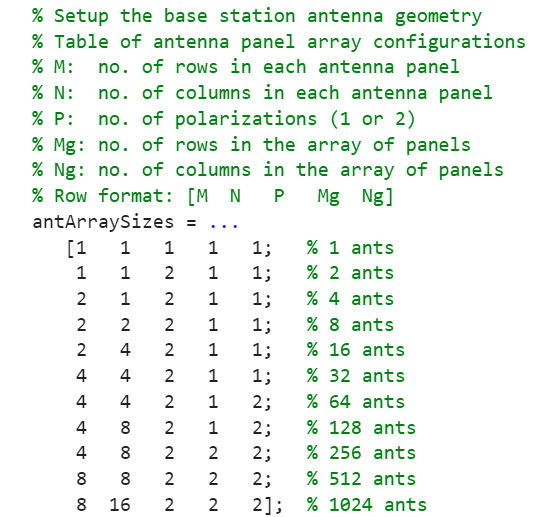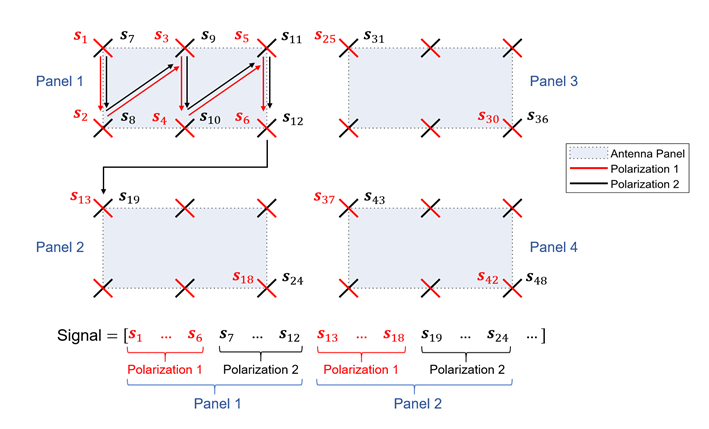

*Copyright 2024 The MathWorks, Inc.*

function storeChannelInfo(dlChannel,gnb,ue,sr)
% Retrieve the channel information
chInfo_1 = info(dlChannel{1});
chInfo_2 = info(dlChannel{1});
numNodes=length(gnb)+length(ue);
% Initialize the CDL channel cell array, maximum channel delay matrix, and the path filter cell array
channelInfo.CDLChannels = cell(numNodes,numNodes);
channelInfo.MaxChannelDelayMatrix = zeros(numNodes,numNodes);
channelInfo.PathFilter = cell(numNodes,numNodes);
% Store channel information between gNB and UE-1 for use during the simulation 
channelInfo.CDLChannels{gnb.ID, ue(1).ID} = dlChannel{1};
channelInfo.MaxChannelDelayMatrix(gnb.ID, ue(1).ID) = ceil(max(chInfo_1.PathDelays*sr)) + chInfo_1.ChannelFilterDelay;
channelInfo.PathFilter{gnb.ID,ue(1).ID} = getPathFilters(channelInfo.CDLChannels{gnb.ID,ue(1).ID}).';
% Store channel information between gNB and UE-2 for use during the simulation 
channelInfo.CDLChannels{gnb.ID, ue(2).ID} = dlChannel{2};
channelInfo.MaxChannelDelayMatrix(gnb.ID, ue(2).ID) = ceil(max(chInfo_2.PathDelays*sr)) + chInfo_2.ChannelFilterDelay;
channelInfo.PathFilter{gnb.ID,ue(2).ID} = getPathFilters(channelInfo.CDLChannels{gnb.ID,ue(2).ID}).';
% Save channel information 
getSetChannelModel(channelInfo);
end